# A. Clapeyron

## 1. Stored energy


$$R_{G,x}=-P$$
 
$$M_{G,y}+PL=0\iff M_{G,y}=-PL$$



$$T_x=-P$$



$$Mf_y=P\cdot z-PL$$


clear all
syms P L z E I d nu G S
assume(d>0)
T(z)=-P;
Mf(z)=P*z-P*L;
W=1/(2*E*I)*int(Mf^2,z,0,L)+1/(2*G*S)*int(T^2,z,0,L)

$$W = \frac{L^{3}\,P^{2}}{6\,\text{E}\,\text{I}}+\frac{L\,P^{2}}{2\,G\,S}$$

## 2. displacement

Clapeyron states that the stored energy equals the work of the force $W_P=\frac{1}{2}Pu$ where $u$ is the displacement in $z=L$, therefore : $u=2W/P$

u=simplify(2*W/P)

$$u = \frac{L\,P\,\left(G\,S\,L^{2}+3\,\text{E}\,\text{I}\right)}{3\,\text{E}\,G\,\text{I}\,S}$$

so that $u=u_{Mf}+u_T=\frac{PL^3}{3EI_y}+\frac{PL}{GS}$

## 3. calculation diameter

The expression of the stress in $\mathrm G$ is $\sigma_{zz}^{max}=\frac{Mf_y(0)}{I_y}\cdot\bigg(-\frac{d}{2}\bigg)$, which is equal to $\sigma_P$

Mf(0)

$$ans = -L\,P$$

sig(d)=-Mf(0)/(pi*d^4/64)*d/2

$$sig(d) = \frac{32\,L\,P}{d^{3}\,\pi }$$


$$d=\bigg(\frac{32PL}{\sigma_P\,\pi}\bigg)^{1/3}$$


P=10e3; L=2; s_p=200e6; E=200e9; nu=0.3;
d=(32*P*L/s_p/pi)^(1/3);
fprintf('d = %1.1f mm',d*1000)

d = 100.6 mm

I=pi*d^4/64; S=pi*d^2/4; G=E/(2*(1+nu));
u_Mf=P*L^3/(3*E*I);
fprintf('u_mf = %1.1f mm',u_Mf*1000)

u_mf = 26.5 mm

u_T=P*L/(G*S);
fprintf('u_T = %1.1f um',u_T*1E6)

u_T = 32.7 um

So in the end, $u=26.5+3.3\times10^{-2}\,\mathrm{mm}$, therefore the contribution of the shear force is negligeable.

# B. Castigliano

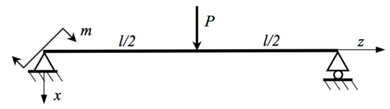

clear all
syms m P L z Rg Rd C1 C2 I E
e1=Rg+Rd+P==0;
e2=m+L/2*P+L*Rd==0;
[A,B]=equationsToMatrix([e1,e2],[Rg,Rd]); 
mat=simplify(inv(A)*B)

$$mat = \left(\begin{array}{c} \frac{2\,m-L\,P}{2\,L}\\ -\frac{m+\frac{L\,P}{2}}{L} \end{array}\right)$$

Rg=simplify(mat(1)); Rd=simplify(mat(2));

T1(z)=Rg; T2(z)=Rg+P;
M1(z)=-int(T1,z)+C1;
M2(z)=-int(T2,z)+C2;
e1=M1(0)==m;
e2=M2(L)==0;
[A,B]=equationsToMatrix([e1,e2],[C1,C2]); mat=inv(A)*B;

M1(z)=subs(M1(z),C1,mat(1))

$$M1(z) = m-\frac{z\,\left(2\,m-L\,P\right)}{2\,L}$$

M2(z)=subs(M2(z),C2,mat(2))

$$M2(z) = L\,\left(P+\frac{2\,m-L\,P}{2\,L}\right)-z\,\left(P+\frac{2\,m-L\,P}{2\,L}\right)$$


W(P)=1/(2*E*I)*(int(M1^2,z,0,L/2)+int(M2^2,z,L/2,L));
W(P)=simplify(W(P))

$$W(P) = \frac{L\,\left(L^{2}\,P^{2}+6\,L\,P\,m+16\,m^{2}\right)}{96\,\text{E}\,\text{I}}$$

u=simplify(diff(W,P))

$$u(P) = \frac{L^{2}\,\left(3\,m+L\,P\right)}{48\,\text{E}\,\text{I}}$$

theta=simplify(diff(W,m))

$$theta(P) = \frac{L\,\left(32\,m+6\,L\,P\right)}{96\,\text{E}\,\text{I}}$$

Application numérique

P=5e3; m=4e3; L=3; E=200e9; a=50e-3; I=a^4/12;
eval(u); fprintf('u = %1.1f mm',eval(u)*1000)

u = 48.6 mm

eval(theta); fprintf('theta = %1.3f rd',eval(theta))

theta = 0.065 rd

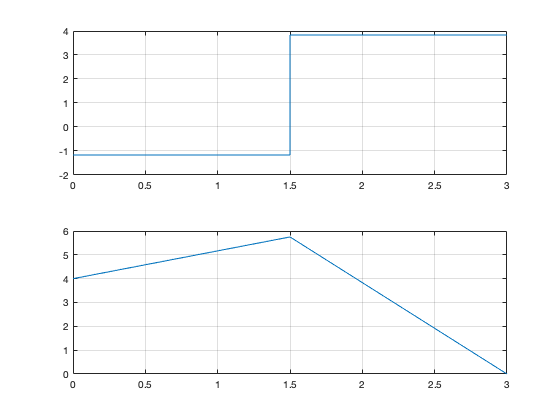

z1=0:L/20:L/2; z2=L/2:L/20:L; z=[z1 z2];
T1=eval(T1(z1)); T2=eval(T2(z2)) ; T=[T1 T2];
figure
ax1 = subplot(2,1,1);
plot(ax1,z,T/1000)
%title('Shear force')
%xticks([0  L/2 L]); xticklabels({'0','L/2','L'})
%ylabel('T_x (kN)','FontSize',14);
grid on
M1=eval(M1(z1)); M2=eval(M2(z2)); M=[M1 M2];
ax2 = subplot(2,1,2);
plot(ax2,z,M/1000)
%xticks([0  L/2 L]); xticklabels({'0','L/2','L'})
%title('Bending moment')
%ylabel('Mf_y (kNm)','FontSize',14);
grid on

# C. Maxwell-Mohr

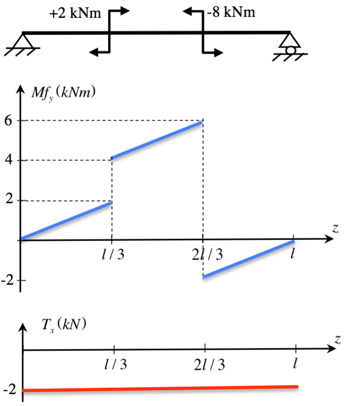

Considering the discontinuities we see that we have two applied moments $m_1=2\,\mathrm{kNm}$ and $m_2=-8\,\mathrm{kNm}$

clear all
syms L m1 m2 z C2 C3 rg rd
assume(L>0)

e1=rg+rd==0;
e2=m1+m2+L*rd==0;
[A B]=equationsToMatrix([e1,e2],[rg,rd]); mat=inv(A)*B

$$mat = \left(\begin{array}{c} \frac{m_{1}+m_{2}}{L}\\ -\frac{m_{1}+m_{2}}{L} \end{array}\right)$$

rg=mat(1); rd=mat(2);

T(z)=rg

$$T(z) = \frac{m_{1}+m_{2}}{L}$$

M1(z)=-int(T,z); M2(z)=-int(T,z)+C2; M3(z)=-int(T,z)+C3;
e1=M1(L/3)+m1==M2(L/3);
e2=M2(2*L/3)+m2==M3(2*L/3);
[A B]=equationsToMatrix([e1,e2],[C2,C3]); mat=inv(A)*B;
C2=mat(1); C3=mat(2);
M2(z)=-int(T,z)+C2; M3(z)=-int(T,z)+C3;
Mf(z)=piecewise(0<=z<L/3,M1(z),L/3<=z<2*L/3,M2(z),2*L/3<=z<=L,M3(z))

$$Mf(z) = \left\{ \begin{array}{cl} -\frac{z\,\left(m_{1}+m_{2}\right)}{L} & \text{ if }3\,z<L\wedge 0\leq z\\ m_{1}-\frac{z\,\left(m_{1}+m_{2}\right)}{L} & \text{ if }L\leq 3\,z\wedge 3\,z<2\,L\\ m_{1}+m_{2}-\frac{z\,\left(m_{1}+m_{2}\right)}{L} & \text{ if }z\leq L\wedge 2\,L\leq 3\,z \end{array}\right.$$

In order to calculate the displacement in $z=L/3$ and the rotation in $z=0$, one can apply the Maxwell-Mohr theorem and therefore define :

case (a)

case (b)

syms rg_a rd_a 
e1=rg_a+rd_a+1==0;
e2=L/3+rd_a*L==0;
[A B]=equationsToMatrix([e1,e2],[rg_a,rd_a]); mat=inv(A)*B

$$mat = \left(\begin{array}{c} -\frac{2}{3}\\ -\frac{1}{3} \end{array}\right)$$

rg_a=mat(1); rd_a=mat(2);
t_a(z)=piecewise(0<=z<L/3,rg_a,L/3<=z<=L,-rd_a)

$$t\_a(z) = \left\{ \begin{array}{cl} -\frac{2}{3} & \text{ if }3\,z<L\wedge 0\leq z\\ \frac{1}{3} & \text{ if }z\leq L\wedge L\leq 3\,z \end{array}\right.$$

mf_a(z)=piecewise(0<=z<L/3,-rg_a*z,L/3<=z<=L,rd_a*z+L/3)

$$mf\_a(z) = \left\{ \begin{array}{cl} \frac{2\,z}{3} & \text{ if }3\,z<L\wedge 0\leq z\\ \frac{L}{3}-\frac{z}{3} & \text{ if }z\leq L\wedge L\leq 3\,z \end{array}\right.$$


syms rg_b rd_b
e1=rg_b+rd_b==0;
e2=1+L*rd_b==0;
[A B]=equationsToMatrix([e1,e2],[rg_b,rd_b]); mat=inv(A)*B

$$mat = \left(\begin{array}{c} \frac{1}{L}\\ -\frac{1}{L} \end{array}\right)$$

rg_b=mat(1); rd_b=mat(2);
t_b(z)=rg_b

$$t\_b(z) = \frac{1}{L}$$

mf_b(z)=-rg_b*z+1

$$mf\_b(z) = 1-\frac{z}{L}$$


syms E I
u=simplify(1/(E*I)*int(Mf*mf_a,z,0,L))

$$u = \frac{L^{2}\,\left(4\,m_{1}-5\,m_{2}\right)}{162\,\text{E}\,\text{I}}$$

theta=simplify(1/(E*I)*int(Mf*mf_b,z,0,L))

$$theta = \frac{L\,\left(m_{1}-2\,m_{2}\right)}{18\,\text{E}\,\text{I}}$$


E=200e9; I=50e-8; L=3;
%h=7e-2; b=1.75e-2;  I=h^3*b/12;
m1=2000; m2=-8000;
u=eval(u); fprintf('u = %1.1f mm',u*1000)

u = 26.7 mm

theta=eval(theta); fprintf('theta = %1.3f rd',theta)

theta = 0.030 rd